%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Authors      :-  Manas Kumar Mishra, Niranjana Vannadil 
% Project name :-  SEA (Statistical Enhancement of Audio)
% Organization :-  IIITDM Kancheepuram
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Noisy clips
% 1. TempleNoisyclip1_Agra.mp3
% 2. TempleNoisyclip2_Agra.mp3
% 3. TempleNoisyclip1_Agra.wav
% 4. TempleNoisyclip2_Agra.wav
% 5. TestAudio4.wav

[samples, fsample] = audioread('TestSongs/TempleNoisyclip1_Agra.wav');

player = audioplayer(samples, fsample);
play(player);

fsample %sampling frequency of audio 

fsample = 44100

samples; %Samples, right and left channel

% PSD Show

ShowPSD(samples, fsample);



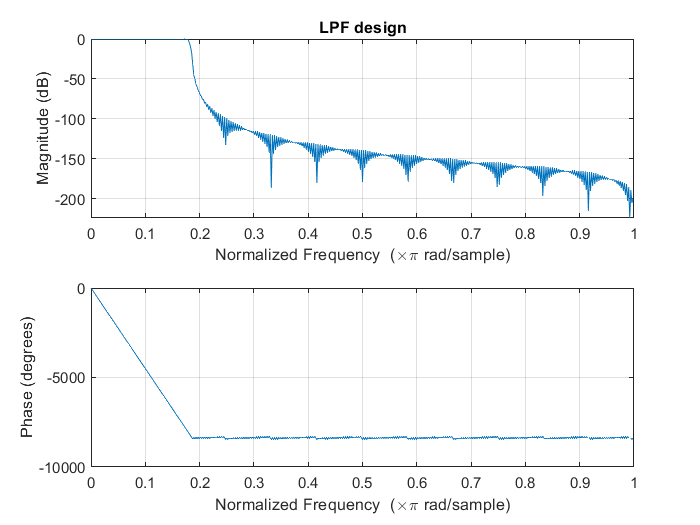

% Preprocessing step
Cutoff = 0.182;

filterLength =500;

filterCoff = impulseResponseOfFilterLPF(Cutoff, filterLength, 3);

NewSamples1 = myFIRFilter(samples(:, 1)', filterCoff);
NewSamples2 = myFIRFilter(samples(:, 2)', filterCoff);
NewSample = [NewSamples1', NewSamples2'];




% player = audioplayer(NewSample, fsample);
% play(player);


% PSD view
ShowPSD(NewSample, fsample);


% Output = MMSESTSA84(NewSample, fsample);

% player = audioplayer(Output, fsample);
% play(player);


a= rand(1, 44100);

W= ceil(0.032*44100)
Window = hamming(W);
overlappPerc=0.75;
sp = 1-overlappPerc

Window=Window(:);
a1= NewSample(:, 1)';
L=length(a1);

SP=fix(W.*sp);

N=fix((L-W)/SP +1); %number of segments

repmat(1:W, N, 1);
repmat((0:(N-1))'*SP,1,W);
Index=(repmat(1:W,N,1)+repmat((0:(N-1))'*SP,1,W))'
hw=repmat(Window,1,N);
Seg=a1(Index);
Seg=a1(Index).*hw;

Seg

% Framing of the sample values
conSampleLength = 0.032

conSampleLength = 0.0320

WinLen = ceil(conSampleLength*fsample);
overlappPerc = 0.75;

[frame1, frame2]= Framing(NewSample,WinLen, overlappPerc, 1);




% Fourier transform of the framed part
FSAMPLE1 = fft(frame1);
FSAMPLE2 = fft(frame2);



% F = FSAMPLE1(1:fix(end), :);

% Experiment 
A = [1, 2, 3, 4;
    2, 4, 5, 6;
    7, 8, 9, 10;
    11, 12, 13, 14];

F = A(1:fix(end));


% Convert Matrix into row vector 
F1 = FSAMPLE1(1:fix(end));
F2 = FSAMPLE2(1:fix(end));


% Magnitude term of fft term
F1_mag = abs(F1);
F2_mag = abs(F2);

% Phase term of the signal
F1_phase = angle(F1);
F2_phase = angle(F2);

